% --------------------------
% Parameters
% --------------------------
N = 32;             % Code length (must be power of 2)
K = 16;              % Number of message bits
u_msg = randi([0,1],1,K);  % Message bits extended to K

% --------------------------
% Step 1: Define frozen and info indices
% ----------------------
% ----
% Generate reliability sequence (example: based on a simple pattern)
reliability = [0 1 2 4 8 16 32 3 5 64 9 6 17 10 18 128 12 33 65 20 256 34 24 36 7 129 66 512 11 40 68 130 ...
        19 13 48 14 72 257 21 132 35 258 26 513 80 37 25 22 136 260 264 38 514 96 67 41 144 28 69 42 ...
        516 49 74 272 160 520 288 528 192 544 70 44 131 81 50 73 15 320 133 52 23 134 384 76 137 82 56 27 ...
        97 39 259 84 138 145 261 29 43 98 515 88 140 30 146 71 262 265 161 576 45 100 640 51 148 46 75 266 273 517 104 162 ...
        53 193 152 77 164 768 268 274 518 54 83 57 521 112 135 78 289 194 85 276 522 58 168 139 99 86 60 280 89 290 529 524 ...
        196 141 101 147 176 142 530 321 31 200 90 545 292 322 532 263 149 102 105 304 296 163 92 47 267 385 546 324 208 386 150 153 ...
        165 106 55 328 536 577 548 113 154 79 269 108 578 224 166 519 552 195 270 641 523 275 580 291 59 169 560 114 277 156 87 197 ...
        116 170 61 531 525 642 281 278 526 177 293 388 91 584 769 198 172 120 201 336 62 282 143 103 178 294 93 644 202 592 323 392 ...
        297 770 107 180 151 209 284 648 94 204 298 400 608 352 325 533 155 210 305 547 300 109 184 534 537 115 167 225 326 306 772 157 ...
        656 329 110 117 212 171 776 330 226 549 538 387 308 216 416 271 279 158 337 550 672 118 332 579 540 389 173 121 553 199 784 179 ...
        228 338 312 704 390 174 554 581 393 283 122 448 353 561 203 63 340 394 527 582 556 181 295 285 232 124 205 182 643 562 286 585 ...
        299 354 211 401 185 396 344 586 645 593 535 240 206 95 327 564 800 402 356 307 301 417 213 568 832 588 186 646 404 227 896 594 ...
        418 302 649 771 360 539 111 331 214 309 188 449 217 408 609 596 551 650 229 159 420 310 541 773 610 657 333 119 600 339 218 368 ...
        652 230 391 313 450 542 334 233 555 774 175 123 658 612 341 777 220 314 424 395 673 583 355 287 183 234 125 557 660 616 342 316 ...
        241 778 563 345 452 397 403 207 674 558 785 432 357 187 236 664 624 587 780 705 126 242 565 398 346 456 358 405 303 569 244 595 ...
        189 566 676 361 706 589 215 786 647 348 419 406 464 680 801 362 590 409 570 788 597 572 219 311 708 598 601 651 421 792 802 611 ...
        602 410 231 688 653 248 369 190 364 654 659 335 480 315 221 370 613 422 425 451 614 543 235 412 343 372 775 317 222 426 453 237 ...
        559 833 804 712 834 661 808 779 617 604 433 720 816 836 347 897 243 662 454 318 675 618 898 781 376 428 665 736 567 840 625 238 ...
        359 457 399 787 591 678 434 677 349 245 458 666 620 363 127 191 782 407 436 626 571 465 681 246 707 350 599 668 790 460 249 682 ...
        573 411 803 789 709 365 440 628 689 374 423 466 793 250 371 481 574 413 603 366 468 655 900 805 615 684 710 429 794 252 373 605 ...
        848 690 713 632 482 806 427 904 414 223 663 692 835 619 472 455 796 809 714 721 837 716 864 810 606 912 722 696 377 435 817 319 ...
        621 812 484 430 838 667 488 239 378 459 622 627 437 380 818 461 496 669 679 724 841 629 351 467 438 737 251 462 442 441 469 247 ...
        683 842 738 899 670 783 849 820 728 928 791 367 901 630 685 844 633 711 253 691 824 902 686 740 850 375 444 470 483 415 485 905 ...
        795 473 634 744 852 960 865 693 797 906 715 807 474 636 694 254 717 575 913 798 811 379 697 431 607 489 866 723 486 908 718 813 ...
        476 856 839 725 698 914 752 868 819 814 439 929 490 623 671 739 916 463 843 381 497 930 821 726 961 872 492 631 729 700 443 741 ...
        845 920 382 822 851 730 498 880 742 445 471 635 932 687 903 825 500 846 745 826 732 446 962 936 475 853 867 637 907 487 695 746 ...
        828 753 854 857 504 799 255 964 909 719 477 915 638 748 944 869 491 699 754 858 478 968 383 910 815 976 870 917 727 493 873 701 ...
        931 756 860 499 731 823 922 874 918 502 933 743 760 881 494 702 921 501 876 847 992 447 733 827 934 882 937 963 747 505 855 924 ...
        734 829 965 938 884 506 749 945 966 755 859 940 830 911 871 639 888 479 946 750 969 508 861 757 970 919 875 862 758 948 977 923 ...
        972 761 877 952 495 703 935 978 883 762 503 925 878 735 993 885 939 994 980 926 764 941 967 886 831 947 507 889 984 751 942 996 ...
        971 890 509 949 973 1000 892 950 863 759 1008 510 979 953 763 974 954 879 981 982 927 995 765 956 887 985 997 986 943 891 998 766 ...
        511 988 1001 951 1002 893 975 894 1009 955 1004 1010 957 983 958 987 1012 999 1016 767 989 1003 990 1005 959 1011 1013 895 1006 1014 1017 1018 ...
        991 1020 1007 1015 1019 1021 1022 1023]+1;  % Random permutation as a basic reliability measure

arr = zeros(1, N);
ind=1;
for i=1:1024
    if(reliability(i)<=N)
        arr(ind)=reliability(i);
        ind=ind+1;
    end
    if(ind==N)
        break;
    end
end

frozen_indices = arr(1:(N-K));
info_indices = setdiff(1:N, frozen_indices);

u = zeros(1, N);
u(info_indices(1:K)) = u_msg;

F = [1 0; 1 1];

% Recursive Kronecker product to get G_N
G = 1;  % Start with identity
n = log2(N);
for i = 1:n
    G = kron(G, F);
end


% Optional: reverse bit order in rows/columns (depends on convention)
% G = bitrevorder(G);

% --------------------------
% Step 4: Encode
% --------------------------
x = mod(u * G, 2);  % Polar encoding using matrix multiplication

% --------------------------
% Output
% --------------------------

disp(u_msg);

     1     1     1     1     1     0     1     0     1     0     0     1     1     0     0     0



disp('Input vector u:');

Input vector u:


disp(u);

     0     0     0     0     0     0     0     1     0     0     0     1     0     1     1     1     0     0     0     0     0     1     0     1     0     0     0     1     1     0     0     0



disp('Encoded vector x:');

Encoded vector x:


disp(x);

     1     1     0     1     1     1     0     1     0     0     0     1     0     0     0     1     0     1     0     0     1     0     1     1     0     1     1     1     1     0     0     0



    -1    -1     1    -1    -1    -1     1    -1     1     1     1    -1     1     1     1    -1     1    -1     1     1    -1     1    -1    -1     1    -1    -1    -1    -1     1     1     1



      -1.8208     -0.31251       1.1792      -1.3486     -0.33237      -1.5016      0.71615      -1.4003      0.48146       1.3178       1.7631     -0.55853       1.3992       1.2298      0.73568      -1.3387       1.5038      -1.3794       1.9797       0.6373      -1.4172      0.67764      -1.0278      -2.2663       1.2305      -1.8602      -0.0888     -0.54263     -0.40646       2.0243      -0.1014       1.1217



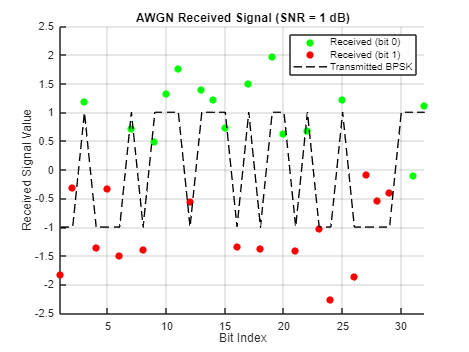

    -1    -1     1    -1    -1    -1     1    -1     1     1     1    -1     1     1     1    -1     1    -1     1     1    -1     1    -1    -1     1    -1    -1    -1    -1     1     1     1



      -1.3235      0.31494      0.97749     -0.62435       -1.597     -0.97853      0.25505      -1.0047      0.86376       1.3849      0.95051     -0.54267       1.4713       1.7392     0.053031       -1.006       0.1781     -0.68496      0.45944      0.73659     -0.92136      0.95783     -0.87421     -0.97322      0.70204     -0.19092     -0.96404      -1.4866      -2.1524      0.69688       0.9933       1.0226



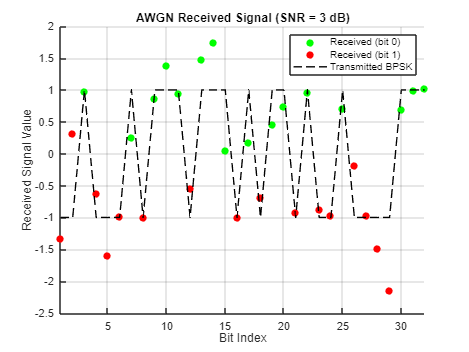

    -1    -1     1    -1    -1    -1     1    -1     1     1     1    -1     1     1     1    -1     1    -1     1     1    -1     1    -1    -1     1    -1    -1    -1    -1     1     1     1



     -0.94446      -1.6853       1.5444      -1.1484     -0.72969     -0.55464      0.99362       -1.535      0.77056      0.77998       1.3645     -0.84642       1.3944       1.5319       1.4169     -0.33059       1.1402      -1.6248       1.0336      0.86063     -0.23771      0.59322     -0.73414     -0.92289      0.82775     -0.68009      -1.1061      -1.7315      -1.3825       1.7207      0.35041      0.96559



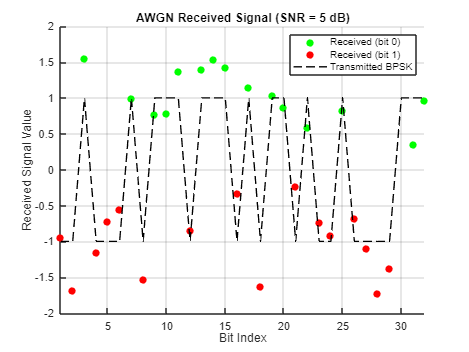


s = 1 - 2 * x;  % BPSK Mapping: 0 -> +1, 1 -> -1


SNRs = [1,3,5];
% SNR in dB (adjust as needed)
for i=1:3
    SNR_dB=SNRs(i);
SNR = 10^(SNR_dB / 10);      % Linear SNR
sigma = sqrt(1 / (2 * SNR)); % Noise standard deviation (unit energy symbols)

noise = sigma * randn(1, N); % AWGN noise vector
r = s + noise;               % Received noisy signal

disp(s);
disp(r);

figure;
hold on; grid on;
title(['AWGN Received Signal (SNR = ', num2str(SNR_dB), ' dB)']);
xlabel('Bit Index');
ylabel('Received Signal Value');
xlim([1 N]);

idx_0 = find(x == 0);
idx_1 = find(x == 1); 

plot(idx_0, r(idx_0), 'go', 'MarkerFaceColor', 'g', 'DisplayName', 'Received (bit 0)');
plot(idx_1, r(idx_1), 'ro', 'MarkerFaceColor', 'r', 'DisplayName', 'Received (bit 1)');

plot(1:N, s, 'k--', 'LineWidth', 1.2, 'DisplayName', 'Transmitted BPSK');
legend('Location', 'northeast');
hold off;
end